clc; clear; close all;

n = 30;
N = 305;

x_n_mesh = transpose((0:(n-1))/n)

x_n_mesh =          0
    0.0333
    0.0667
    0.1000
    0.1333
    0.1667
    0.2000
    0.2333
    0.2667
    0.3000


x_N_mesh = transpose((0:(N-1))/N)

x_N_mesh =          0
    0.0033
    0.0066
    0.0098
    0.0131
    0.0164
    0.0197
    0.0230
    0.0262
    0.0295


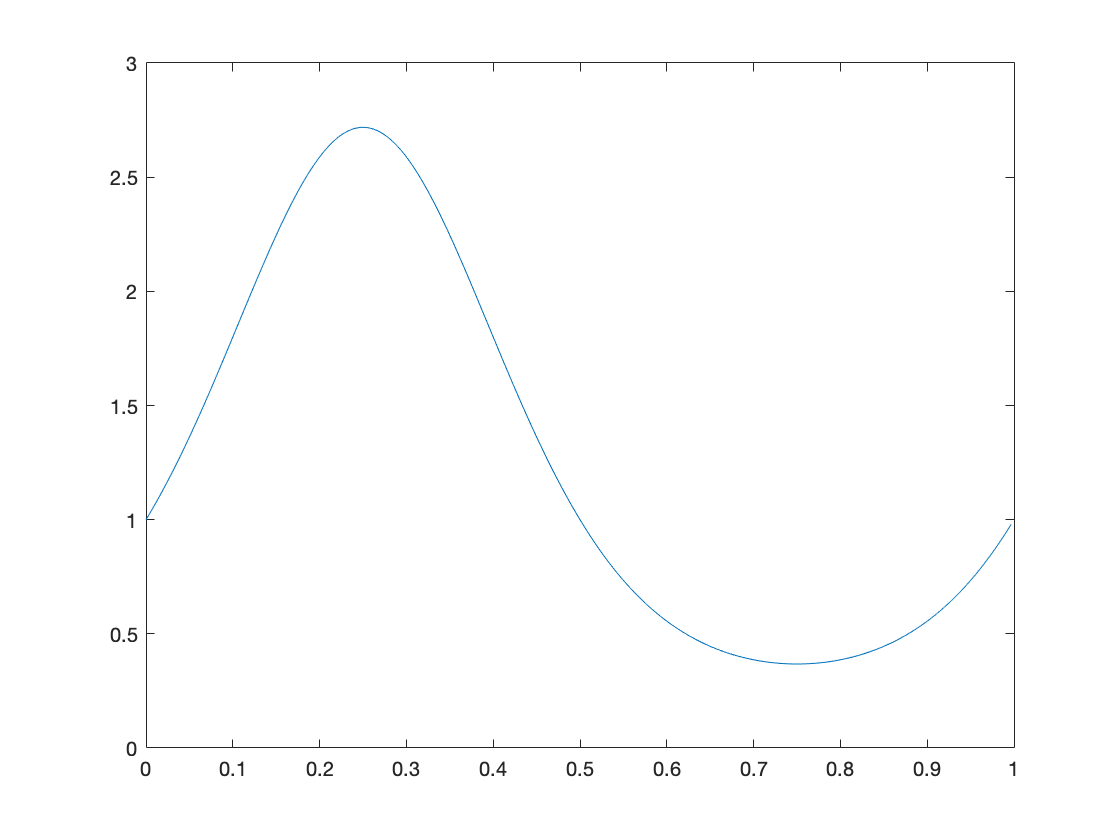


f = @(x) transpose(exp(sin(2*pi*x)));

fc_coeffs = fftshift(1/n * fft(f(x_n_mesh)));

padded_fc_coeffs = [zeros(1, floor((N-n)/2)), fc_coeffs, zeros(1, ceil((N-n)/2))];
f_numeric = N*real(ifft(ifftshift(padded_fc_coeffs)));

figure;
plot(x_N_mesh, f_numeric)